% Autor: Luis Eduardo Arenas Deseano
% Proyecto: Sistemas Inteligentes
% Descripción: PRueba de algoritmO de SVM con Multiclase
% Fecha: 1/12/2024

function [X, Y] = generate_data(numClasses, pointsPerClass, overlapLevel)
    rng(1); % Para reproducibilidad
    X = [];
    Y = [];
    for i = 1:numClasses
        % Ajustar la dispersión para simular superposición
        if i <= overlapLevel
            spread = 2.5; % Más superposición
        else
            spread = 0.7; % Menos superposición
        end
        X_class = spread * randn(pointsPerClass, 2) + (i * 5);
        Y_class = i * ones(pointsPerClass, 1);
        X = [X; X_class];
        Y = [Y; Y_class];
    end
end


Función Auxiliar para Graficar las Fronteras de Decisión para Cada Par de Clases

function plot_decision_boundaries(svmModel, X, Y, titleText)
    % Graficar los datos de las clases
    gscatter(X(:,1), X(:,2), Y);
    hold on;

    % Crear una malla para el área de predicción
    d = 0.02;
    [x1Grid, x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)), min(X(:,2)):d:max(X(:,2)));
    xGrid = [x1Grid(:), x2Grid(:)];

    % Para cada clasificador binario, dibujar su frontera de decisión
    for i = 1:numel(svmModel.BinaryLearners)
        % Predecir el puntaje para la clase binaria
        [~, score] = predict(svmModel.BinaryLearners{i}, xGrid);
        
        % Usar solo la primera columna del puntaje para la frontera de decisión
        contour(x1Grid, x2Grid, reshape(score(:,1), size(x1Grid)), [0, 0], 'k--', 'LineWidth', 1.5);
    end

    title(titleText);
    xlabel('Eje X1');
    ylabel('Eje X2');
    legend('Clase 1', 'Clase 2', 'Clase 3');
    hold off;
    drawnow;
end

Función Auxiliar para Graficar la Matriz de Confusión y la Curva ROC

function evaluate_model(svmModel, X, Y, numClasses)
    % Predicciones para la matriz de confusión
    Y_pred = predict(svmModel, X);
    figure;
    confusionchart(Y, Y_pred);
    title('Matriz de Confusión');
    
    % Graficar las curvas ROC
    [~, scores] = predict(svmModel, X);
    figure;
    hold on;
    for i = 1:numClasses
        [Xroc, Yroc, ~, AUC] = perfcurve(Y == i, scores(:, i), true);
        plot(Xroc, Yroc, 'DisplayName', sprintf('Clase %d (AUC = %.2f)', i, AUC));
    end
    xlabel('Tasa de Falsos Positivos');
    ylabel('Tasa de Verdaderos Positivos');
    title('Curva ROC para cada Clase');
    legend show;
    hold off;
end


Escenario 1: Clases Separadas

function svm_separated_classes(numClasses, pointsPerClass)
    [X, Y] = generate_data(numClasses, pointsPerClass, 0); % Sin superposición

    % Entrenar el modelo con kernel RBF
    svmModel = fitcecoc(X, Y, 'Learners', templateSVM('KernelFunction', 'rbf'));

    % Graficar fronteras de decisión y evaluar el modelo
    figure;
    plot_decision_boundaries(svmModel, X, Y, 'Clases Separadas');
    evaluate_model(svmModel, X, Y, numClasses);
end



Escenario 2: Superposición Parcial

function svm_partial_overlap(numClasses, pointsPerClass, overlapClasses)
    [X, Y] = generate_data(numClasses, pointsPerClass, overlapClasses);

    % Entrenar el modelo con kernel RBF
    svmModel = fitcecoc(X, Y, 'Learners', templateSVM('KernelFunction', 'rbf'));

    % Graficar fronteras de decisión y evaluar el modelo
    figure;
    plot_decision_boundaries(svmModel, X, Y, 'Superposición Parcial');
    evaluate_model(svmModel, X, Y, numClasses);
end



Escenario 3: Alta Superposición

function svm_high_overlap(numClasses, pointsPerClass)
    [X, Y] = generate_data(numClasses, pointsPerClass, numClasses); % Todas las clases con alta superposición

    % Entrenar el modelo con kernel RBF
    svmModel = fitcecoc(X, Y, 'Learners', templateSVM('KernelFunction', 'rbf'));

    % Graficar fronteras de decisión y evaluar el modelo
    figure;
    plot_decision_boundaries(svmModel, X, Y, 'Alta Superposición');
    evaluate_model(svmModel, X, Y, numClasses);
end



Función Principal de Entrenamiento Incremental Usando fitcecoc

function svmModel = incremental_svm_training(X, Y, titleText)
    uniqueClasses = unique(Y);
    for i = 1:length(uniqueClasses)
        % Crear un modelo SVM multiclase con fitcecoc para cada clase
        svmModel = fitcecoc(X, Y, 'Learners', templateSVM('KernelFunction', 'linear'));
        plot_svm_progress(svmModel, X, Y, sprintf('%s - Paso %d', titleText, i));
        pause(1); % Pausar para simular el entrenamiento en tiempo real
    end
end


Ejecución de Ejemplos

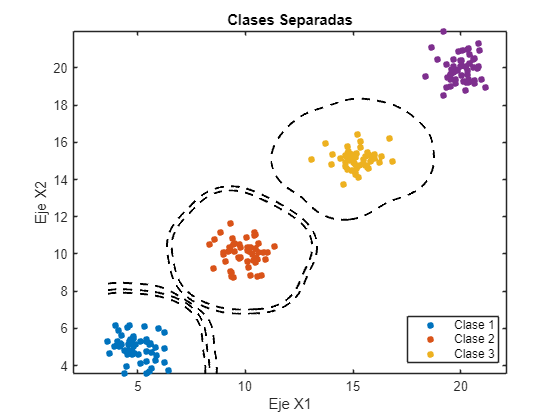

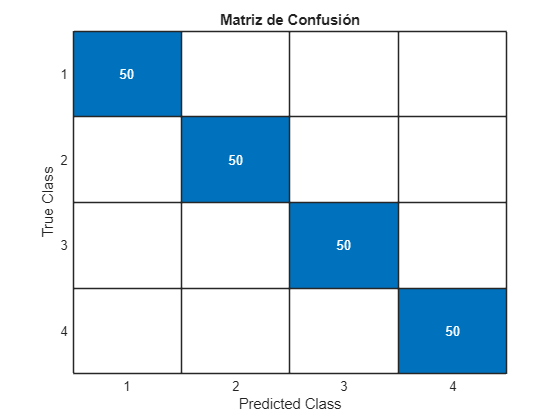

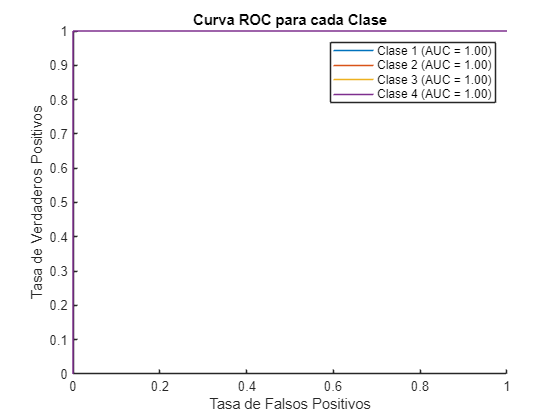

% Escenario 1: Clases Separadas
svm_separated_classes(4, 50);

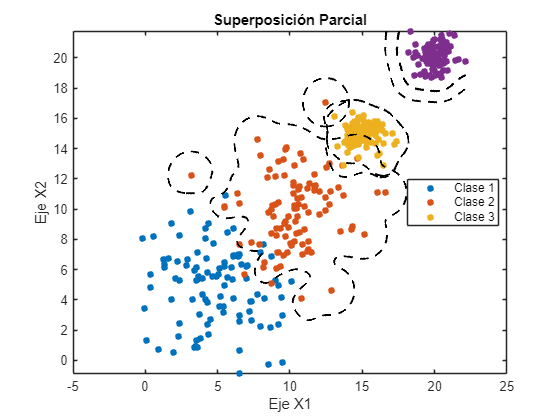

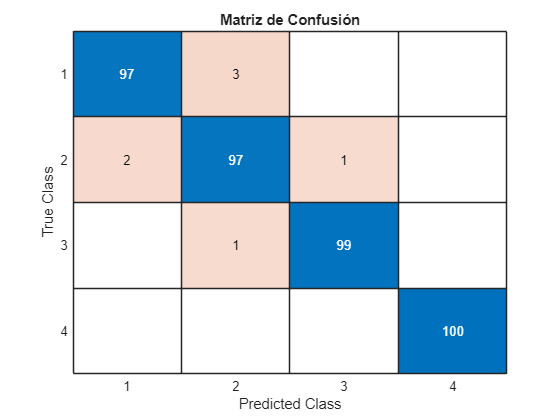

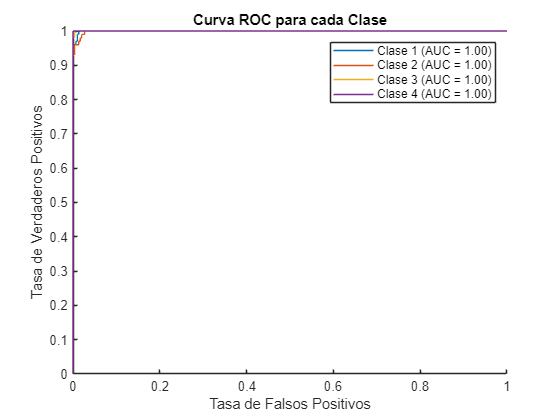


% Escenario 2: Superposición Parcial (1 de 3 clases se superponen)
svm_partial_overlap(4, 100, 2);

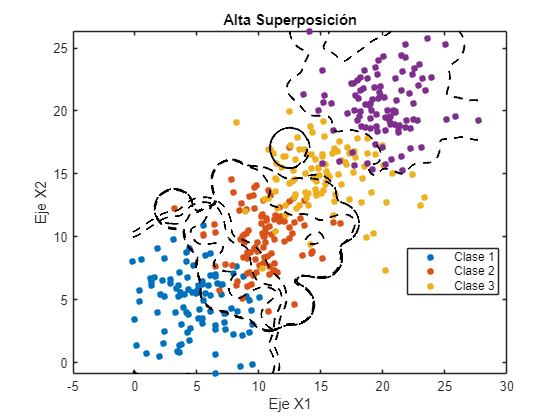

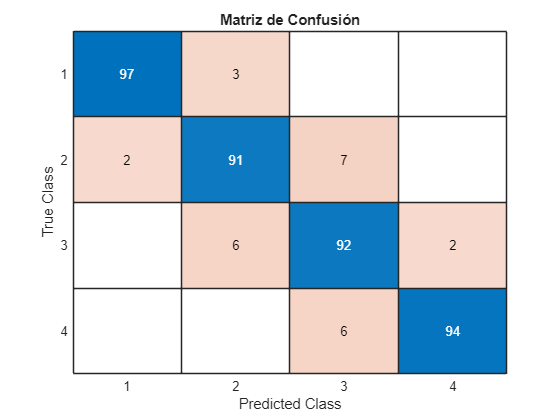

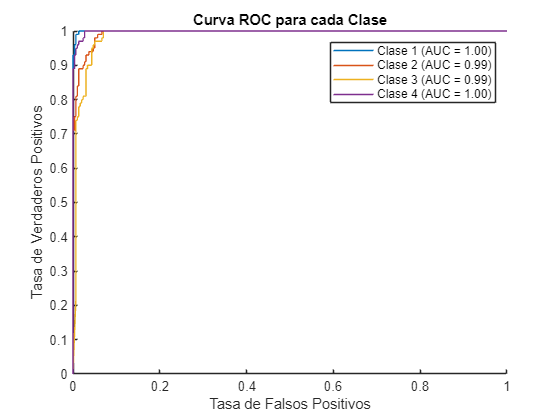


% Escenario 3: Alta Superposición
svm_high_overlap(4, 100);